clear, clc
close all
datadir = 'G:\A_arousal_analysis\data';
% datadir = '/Volumes/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'FC_UESTC_s6.mat'))
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'fig_cols.mat'))
cols = cols./255;
cols1 = cols1./255;
FC = atanh(FC);
FC(isnan(FC)) = 0;
FC(~isfinite(FC)) = 0;
PE = [ones(size(FC,1), 1) FC(:, parcel_idx)] * b_pls;
clear FC*
BDI_MDD_HC = BDIsorted(32:end);
excluded = isnan(BDI_MDD_HC);
PE_MDD_HC = PE(32:end, :);

## classification

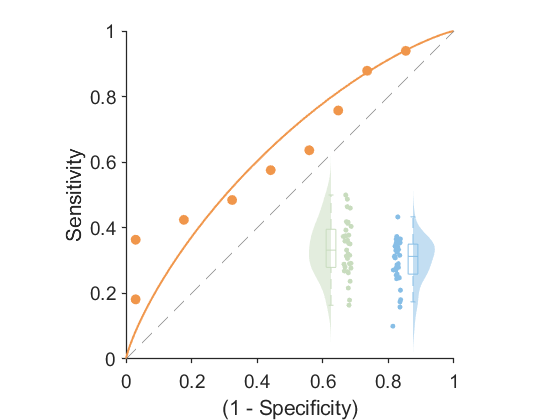

plotRocCurve(PE_MDD_HC(:,1), [zeros(34, 1);ones(33, 1)], 'roc_color', cols(1,:), 'g1_color',cols1(8,:), 'g0_color', cols1(4,:))
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)

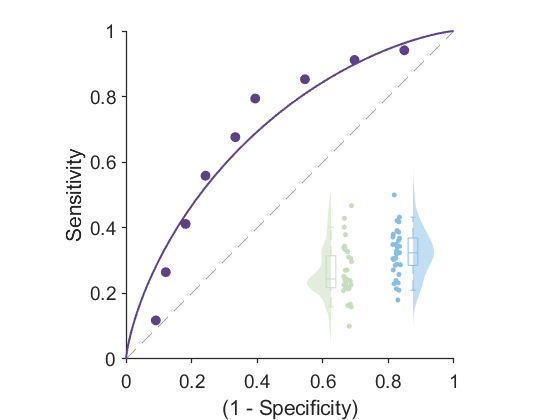

set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_PAES_UESTC_classification', '-r400')
% close all

plotRocCurve(PE_MDD_HC(:,2), [ones(34, 1);zeros(33, 1)], 'roc_color', cols(3,:), 'g1_color',cols1(4,:), 'g0_color', cols1(8,:), 'changeposition', true)
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)

set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_NAES_UESTC_classification', '-r400')
% close all

## PAES response

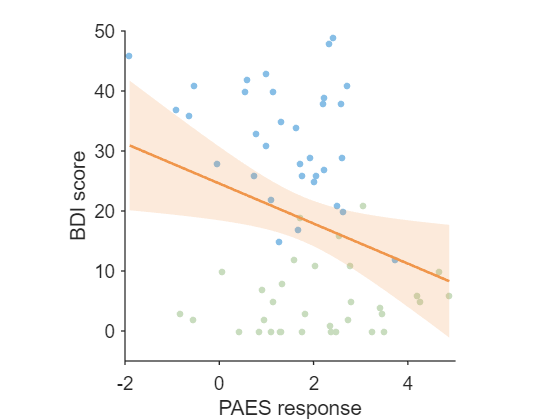

y = BDI_MDD_HC(~excluded);
x = PE_MDD_HC(~excluded, 1);

tbl = table(x(:), y(:), 'VariableNames', {'x','y'});
mdl = fitlm(tbl, 'y ~ x');

% grid for smooth line + CI
xg = linspace(min(x), max(x), 200)';
[yg, yCI] = predict(mdl, xg, 'Alpha', 0.05);

figure; hold on
scatter(x(1:33), y(1:33), 25, cols1(4,:), 'filled')  
scatter(x(34:end), y(34:end), 25, cols1(8,:), 'filled')

% shaded 95% CI
fill([xg; flipud(xg)], [yCI(:,1); flipud(yCI(:,2))], ...
	cols(1,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% fitted line
plot(xg, yg, 'Color', cols(1,:), 'LineWidth', 2);

xlabel('PAES response');
ylabel('BDI score'); 
set(gca,'YLim', [-5 50], 'ytick',0:10:50, 'XLim', [-2 5], 'xtick',-2:2:5, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)
axis square

set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_PAES_BDI_UESTC', '-r400')
% close all

## NAES response

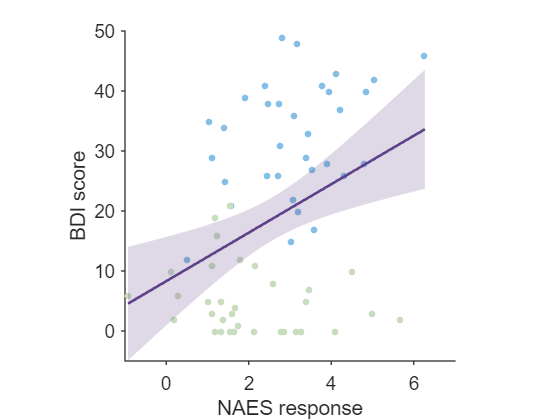

y = BDI_MDD_HC(~excluded);
x = PE_MDD_HC(~excluded, 2);

tbl = table(x(:), y(:), 'VariableNames', {'x','y'});
mdl = fitlm(tbl, 'y ~ x');

% grid for smooth line + CI
xg = linspace(min(x), max(x), 200)';
[yg, yCI] = predict(mdl, xg, 'Alpha', 0.05);

figure; hold on
scatter(x(1:33), y(1:33), 25, cols1(4,:), 'filled')  
scatter(x(34:end), y(34:end), 25, cols1(8,:), 'filled')

% shaded 95% CI
fill([xg; flipud(xg)], [yCI(:,1); flipud(yCI(:,2))], ...
	cols(3,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% fitted line
plot(xg, yg, 'Color', cols(3,:), 'LineWidth', 2);

xlabel('NAES response');
ylabel('BDI score'); 
set(gca,'YLim', [-5 50], 'ytick',0:10:50, 'XLim', [-1 7], 'xtick',0:2:6, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)
axis square

set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_NAES_BDI_UESTC', '-r400')
% close all